# IET-GPR documentation

## Example 1

Load and plot data from a GSSI-StructureScan Mini GPR.

### Start the IET-GPR software

Run the script **ietgpr** to start using the IET-GPR function set.

clear
run('..\ietgpr')

Note that is not necessary to move the folder with the functions to the directory from which to work.

### Load a GPR file

Load a dzt file generated by a GSSI-StructureScan Mini GPR, using **readdzt** function.

filename = 'data\File____001.dzt';
[data, dataHeader] = readdzt(filename)

data =       -35232      -35696      -36096      -35696      -35680      -35120      -35104      -35856      -35696      -36112      -35440      -37520      -37536      -36064      -35888      -37328      -36384      -37120      -36032      -36048      -36512      -36560      -36800      -36080      -37280      -37536      -37392      -37296      -38080      -37136      -37744      -35936      -37024      -36864      -37472      -38256      -37232      -38000      -36848      -37856      -37808      -37200      -37936      -38320      -36608      -37232      -37568      -36448      -37312      -37872
      -35952      -35216      -35952      -35952      -35440      -35904      -34944      -36176      -36064      -35712      -36576      -36416      -37632      -35296      -36432      -37616      -36336      -36832      -37440      -36864      -36304      -36992      -36656      -37088      -36992      -37008      -37600      -37488      -37712      -37936      -36704      -37888      -3

dataHeader = struct with fields:
    samplesPerTrace: 254
      scansPerMeter: 800
      startPosition: 0
    nanosecPerTrace: 10
       numOfColumns: 863


The variable *data* contains the B-Scan data, while the variable *dataHeader* contains the B-Scan general information. This information includes the number of samples per trace or vertical resolution (*samplesPerTrace*), the two-way travel time (in nanoseconds) of every trace or signal (*nanosecPerTrace*), the number of columns or traces (*numOfColumns*), the start position (*startPosition*), and the number of scans (or traces) per meter (*scansPerMeter*). The header information is esencial in some functions and can be updated in others.

### Plot a B-Scan

Plot a B-Scan of the loaded file, using **plotbscan** function. If the relative permittivity is entered, the y-axis is changed to depth.

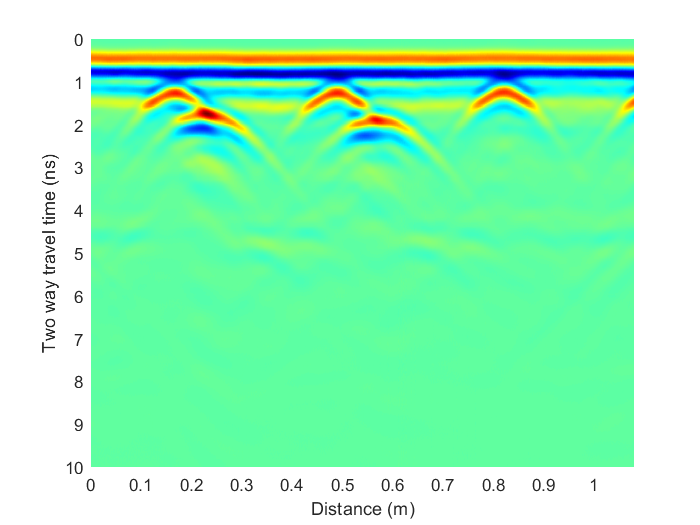

plotbscan(data, dataHeader);

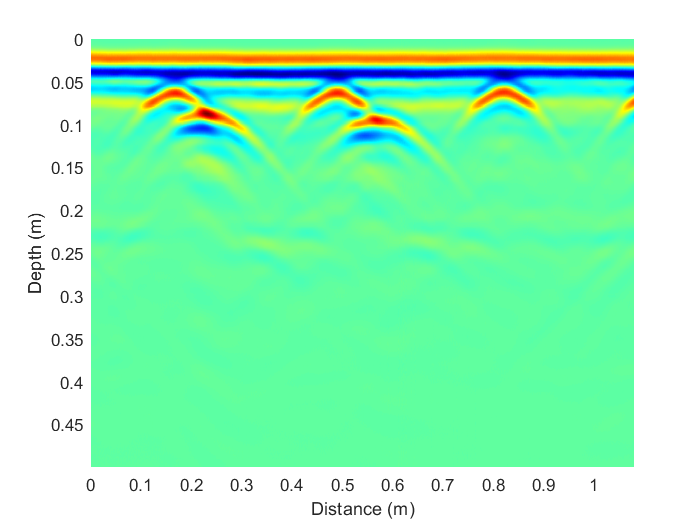

plotbscan(data, dataHeader, 9);

In both cases, the function returns a figure handle that allows the graph to be edited.

### Plot a series of A-Scans

Plot a series of A-Scans, using **plotascan** function. The A-Scans correspond to the traces between two positions.

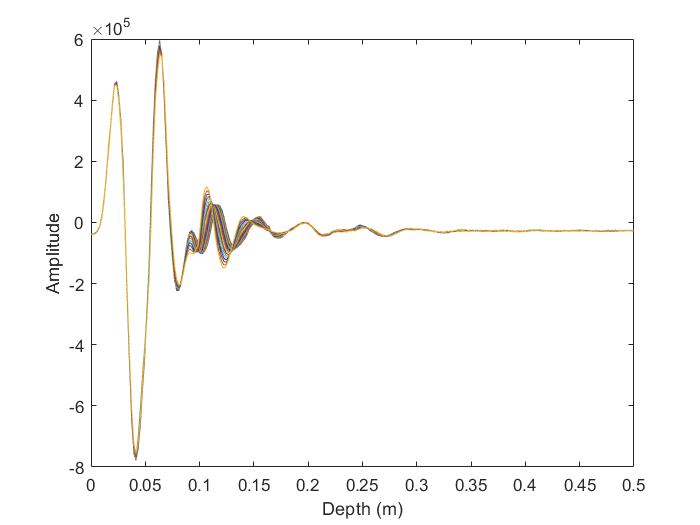

plotascan(data, dataHeader, 0.48, 0.50, 9);